%Number 1A
p = @(x) polyval([1 0 0 0 0 -1],x);
X = linspace(-2,2,6);
Y = p(X);
x = -1.7;
error = abs(p(x)-linterp(X,Y,x))

error = 3.5527e-15


%Number 1B
% Lagrange interpolation will fail if there is more than 1 point
% assigned to a single value. Basically if all the numbers aren't unique.

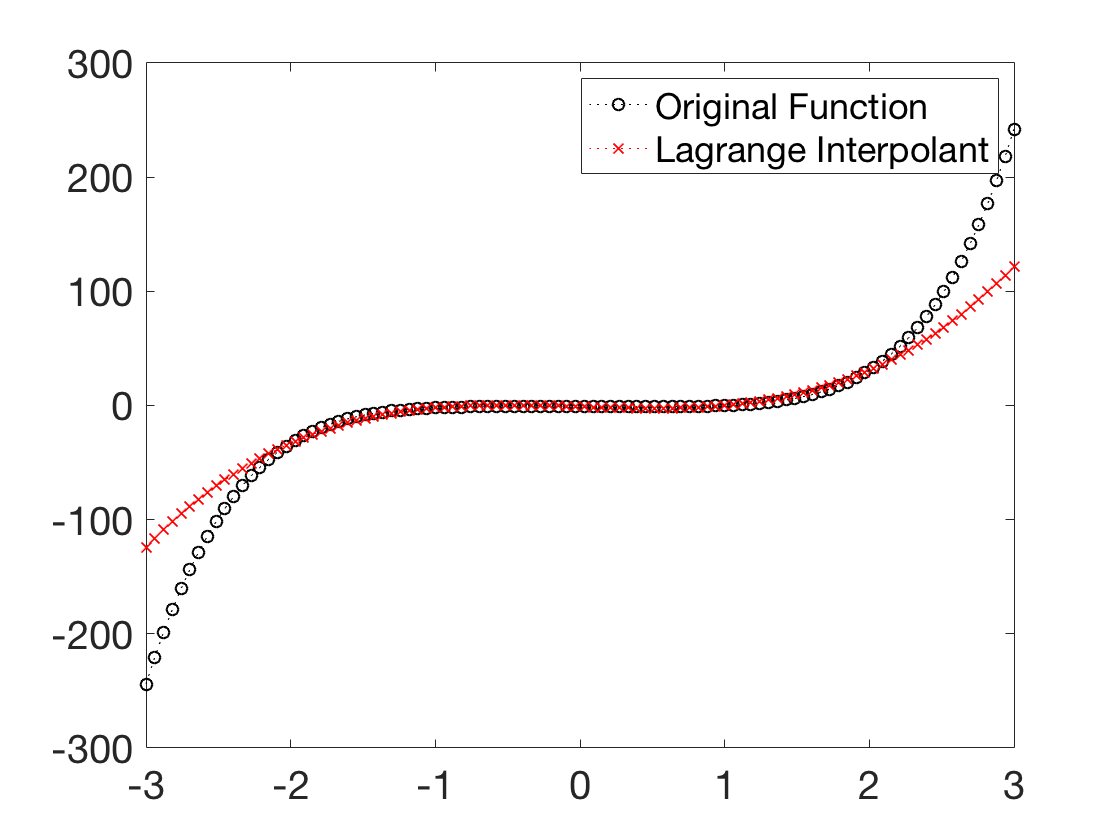

%Numer 1C
p = @(x) polyval([1 0 0 0 0 -1],x);
X = linspace(-2,2,5);
Y = p(X);
x = linspace(min(X)-1, max(X)+1, 100);
plot(x, p(x), 'ko:', x, linterp(X, Y, x), 'rx:');
legend('Original Function','Lagrange Interpolant')
set(gca,'FontSize',20);

%Question 2
%Collaborated with Brandon Dang
x = [-3,2];
y = mypoly(x)

y =      1     1    -6


function y = linterp(X,Y,x)
y = 0;
for i = 1:numel(X)
    yy = Y(i);
    for j = 1:numel(X)
        if i~=j
            yy = yy .* (x-X(j))/(X(i)-X(j));
        end
    end
    y = y+yy;
end
end

function p=mypoly(x)
p=conv([1,-x(1)],[1,-x(2)]);
    for i=3:length(x)
        p=conv(y,[1,-x(i)]);
    end 
end